# Experiment 1

This Live Script contains the experimental setup for the section *"Power flow results for single-phase networks"*  included in the draft paper:

**"A Quadratic Approximation of AC Power Flows in Transformed Polar Coordinates" **

by Wilson Gonzalez-Vanegas and Carlos E. Murillo-Sanchez

Submitted on 29-jun-2025 for consideration in the journal:

 [e-Prime - Advances in Electrical Engineering, Electronics and Energy](https://www.sciencedirect.com/journal/e-prime-advances-in-electrical-engineering-electronics-and-energy)

*Note: MATLAB R2023a is the oldest version where this Live Script was successfully tested. *

We compare the power flow solutions obtained using the proposed Quadratic Approximation in Transformer Polar Coordinates (QTPC) with those of the exact AC formulation over numerous MATPOWER test cases for single-phase networks. The following performance metrics are calculated:

- The *Root Mean Square Error* *(RMSE)*, both for voltage angles and voltage magnitudes defined as:

$RMSE(\mathbf{V}_a) = \frac{\left|\left|\mathbf{V}_a^{QTPC}-\mathbf{V}_a^{AC}\right|\right|_2}{\sqrt{n_{\mathcal{B}}}}$,  $RMSE(\mathbf{V}_m) = \frac{\left|\left|\mathbf{V}_m^{QTPC}-\mathbf{V}_m^{AC}\right|\right|_2}{\sqrt{n_{\mathcal{B}}}}}$,

            where $n_{\mathcal{B}}}$ is the number of system buses.

- The *Maximum Percentage Relative Error (MPRE) *for voltage magnitudes defined as:


$$$MPRE(\mathbf{V}_m)=\max\left\{\frac{\left| \mathbf{V}_m^{QTPC} - \mathbf{V}_m^{AC}  \right|}{\left|\mathbf{V}_m^{AC} \right|} \times 100\% \right\}$ $$


- The *number of Newton-Raphson iterations* required to reach a solution within the default MATPOWER tolerance.

- The elapsed time for finding the solutions for both formulations.

We begin by defining the MATPOWER test cases that will be used in this experiment, ordered by an increasing number of buses:

transmission = {'case4gs', 'case5', 'case6ww', 'case9', 'case14', 'case24_ieee_rts', ...
         'case30', 'case_ieee30', 'case39', 'case57', 'case60nordic', 'case_RTS_GMLC', ...
         'case118', 'case145', 'case_ACTIVSg200', 'case300', 'case_ACTIVSg500', ...
         'case_ACTIVSg2000', 'case2383wp', 'case2736sp', 'case2737sop', 'case2746wop', ...
         'case2746wp', 'case3120sp'};

distribution = {'case4_dist', 'case10ba', 'case12da', 'case15da', 'case15nbr', ...
             'case16ci', 'case17me', 'case18', 'case18nbr', 'case22', ...
             'case28da', 'case33bw', 'case33mg', 'case34sa', 'case38si', ...
             'case51ga', 'case51he', 'case69', 'case70da', 'case74ds', 'case85', ...
             'case94pi', 'case118zh', 'case141'};

cases = [transmission distribution];

Now, we define the MATPOWER options for running power flows under both formulations:

mpopt_ac = mpoption('out.all',0,'verbose',0);
mpopt_qtpc = mpoption('model','TPC','out.all',0,'verbose',0);
mpopt_qtpc.pf.tpc.form = 'QUAD';

Then, we create the Matpower task objects for power flow tasks (`mpt_pf`) for the two formulations:

mpt_pf_ac = mp.task_pf;
mpt_pf_qtpc = wgv.task_pf();

Afterward, we loop through all the test cases and run power flows using the exact AC and QTPC formulations, setting a flat start for each of them:

define_constants;
nc = length(cases);
success = zeros(nc,2);
num_ite = zeros(nc,2);
et = zeros(nc,2);
for c = 1:nc
    mpc = loadcase(cases{c});
    nb = size(mpc.bus,1);
    mpc.bus(:,VA) = zeros(nb,1);
    mpc.bus(:,VM) = ones(nb,1);
    res_ac = mpt_pf_ac.run(mpc,mpopt_ac);
    res_qtpc = mpt_pf_qtpc.run(mpc,mpopt_qtpc);
    va_ac.(cases{c}) = res_ac.dm.elements.bus.tab.va;
    vm_ac.(cases{c}) = res_ac.dm.elements.bus.tab.vm;
    va_qtpc.(cases{c}) = res_qtpc.dm.elements.bus.tab.va;
    vm_qtpc.(cases{c}) = res_qtpc.dm.elements.bus.tab.vm;
    success(c,:) = [res_ac.mm.soln.eflag
                    res_qtpc.mm.soln.eflag]';
    num_ite(c,:) = [res_ac.mm.soln.output.iterations
                    res_qtpc.mm.soln.output.iterations]';
    et(c,:) = [res_ac.mm.soln.output.et
               res_qtpc.mm.soln.output.et]';
end

Now, we compute all the remaining performance metrics and display them in a single table:

rmse_va = zeros(nc,1);
rmse_vm = zeros(nc,1);
mpre_vm = zeros(nc,1);

for c = 1:nc
    C = cases{c};
    nb = length(vm_ac.(C));
    rmse_va(c) = 1/sqrt(nb) * norm(va_qtpc.(C) - va_ac.(C));
    rmse_vm(c) = 1/sqrt(nb) * norm(vm_qtpc.(C) - vm_ac.(C));
    mpre_vm(c) = max(abs( (vm_qtpc.(C) - vm_ac.(C)) ./ vm_ac.(C))) * 100;
end

results = table(cases', success(:,1), success(:,2), rmse_va, rmse_vm, mpre_vm);

results.Properties.VariableNames = {
                'Case','Status AC','Status QTPC', 'RMSE(Va) p.u.','RMSE(Vm) rad','MPRE(Vm) %'}

results = 48×6 table
           Case            Status AC    Status QTPC    RMSE(Va) p.u.    RMSE(Vm) rad    MPRE(Vm) %
    ___________________    _________    ___________    _____________    ____________    __________

    {'case4gs'        }        1             1           0.0011366       3.0234e-05      0.0061993
    {'case5'          }        1             1           0.0017995       3.7615e-06     0.00085022
    {'case6ww'        }        1             1            0.011962       1.3812e-05      0.0026065
    {'case9'          }        1             1           0.0078259       0.00027382       0.038556
    {'case14'         }        1             1           0.0069712       0.00015781       0.033808
    {'case24_ieee_rts'}        1             1            0.030855       0.000206

And make plots with the number of iterations and elapsed times:

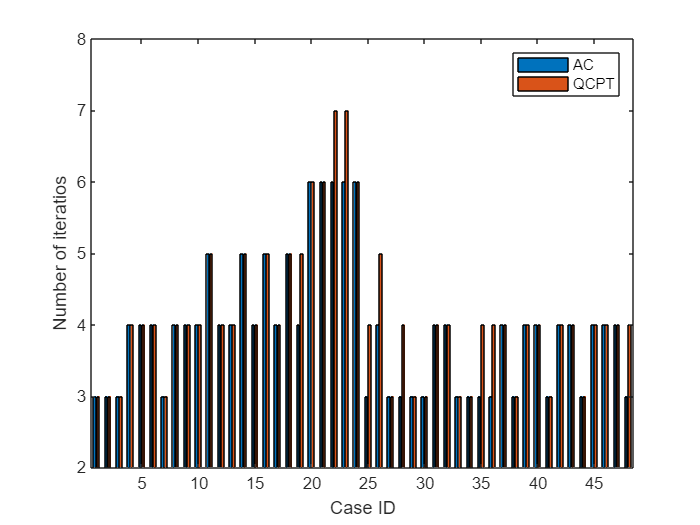

figure; 
bp = bar(num_ite);
ylim([2 8])
xlabel('Case ID');
ylabel('Number of iteratios');
legend({'AC','QCPT'},'Location','northeast')

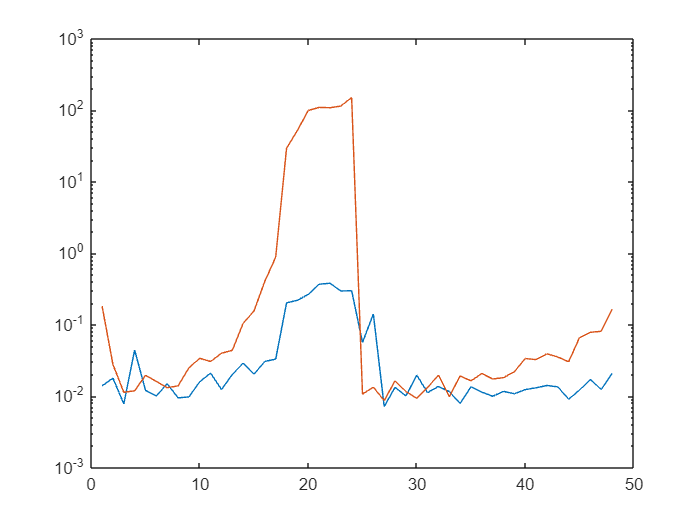


figure;
plot(et);
set(gca,'Yscale','log')